## Nathan Zechar Wright State University 2021 - Intro to FDTD

clear;

#### Define Simulation Based off Source and Wavelength

f0         = 1e6;             % Frequency of Source        [Hertz]
Lf         = 10;              % Divisions per Wavelength   [unitless]
[Lx,Ly]    = deal(8,8);       % Wavelengths x,y            [unitless]
nt         = 500;            % Number of time steps       [unitless]

#### Spatial and Temporal System

e0 = 8.854*10^-12;  % Permittivity of vacuum [farad/meter]
u0 = 4*pi*10^-7;    % Permeability of vacuum [henry/meter]
c0 = 1/(e0*u0)^.5;  % Speed of light         [meter/second]
L0  = c0/f0;        % Freespace Wavelength   [meter]
t0  = 1/f0;         % Source Period          [second]

[Nx,Ny] = deal(Lx*Lf,Ly*Lf);    % Points in x,y           [unitless]
x  = linspace(0,Lx,Nx+1)*L0;    % x vector                [meter]
y  = linspace(0,Ly,Ny+1)*L0;    % y vector                [meter]
[dx,dy] = deal(x(2),y(2));      % x,y,z increment         [meter]
dt = (dx^-2+dy^-2)^-.5/c0*.99;  % Time step CFL condition [second]

#### Simulate

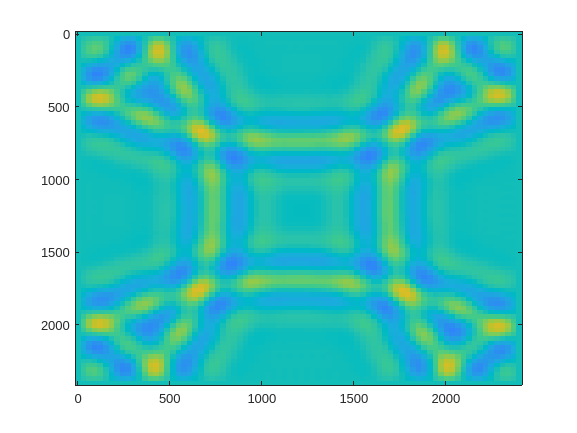

[Hx,Hy,Ez] = deal(zeros(Nx,Ny));           % Magnetic and Electric Fields
[udy,udx]  = deal(dt/(u0*dy),dt/(u0*dx));  % H Field Coefficients
[edx,edy]  = deal(dt/(e0*dx),dt/(e0*dy));  % E Field Coefficients
for t=1:nt
    % Magnetic field update    
    Hx(1:Nx-1,1:Ny-1) = Hx(1:Nx-1,1:Ny-1)-udy*diff(Ez(1:Nx-1,:),1,2);
    Hy(1:Nx-1,1:Ny-1) = Hy(1:Nx-1,1:Ny-1)+udx*diff(Ez(:,1:Ny-1),1,1);
    
    % Electric field update
    Ez(2:Nx-1,2:Ny-1) = Ez(2:Nx-1,2:Ny-1)+...
        edx*diff(Hy(1:Nx-1,2:Ny-1),1,1)-edy*diff(Hx(2:Nx-1,1:Ny-1),1,2);
    Ez(round(Nx/2),round(Ny/2)) = Ez(round(Nx/2),round(Ny/2))+...
        sin(2*pi*f0*dt*t).*exp(-.5*((t-20)/8)^2);
    
    imagesc(x,y,Ez); clim([-0.1 0.1]); drawnow; 
end